# Transfer Learning to predict Musical Instruments

%% creating a datastore for spectrograms. The datastore conatians images of [227, 227] sizes.
spectrods= imageDatastore('Spectrograms',"IncludeSubfolders",true,"LabelSource","foldernames")

spectrods =   ImageDatastore with properties:

                       Files: {
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img321.jpg';
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img322.jpg';
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img323.jpg'
                               ... and 1670 more
                              }
                      Labels: [Bells; Bells; Bells ... and 1670 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


[trainimgs, testimgs, validimgs] = splitEachLabel(spectrods,0.8,0.1,0.1,'randomized');

## Modifying the ALex network

net = alexnet

net =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]


layers = net.Layers;
outlayer=[fullyConnectedLayer(14), softmaxLayer(), classificationLayer()];  %% They are 14 types of musical instruments in the datastore 
layers(end-2:end)=outlayer;

## Setting up the Training Options and Training the Network

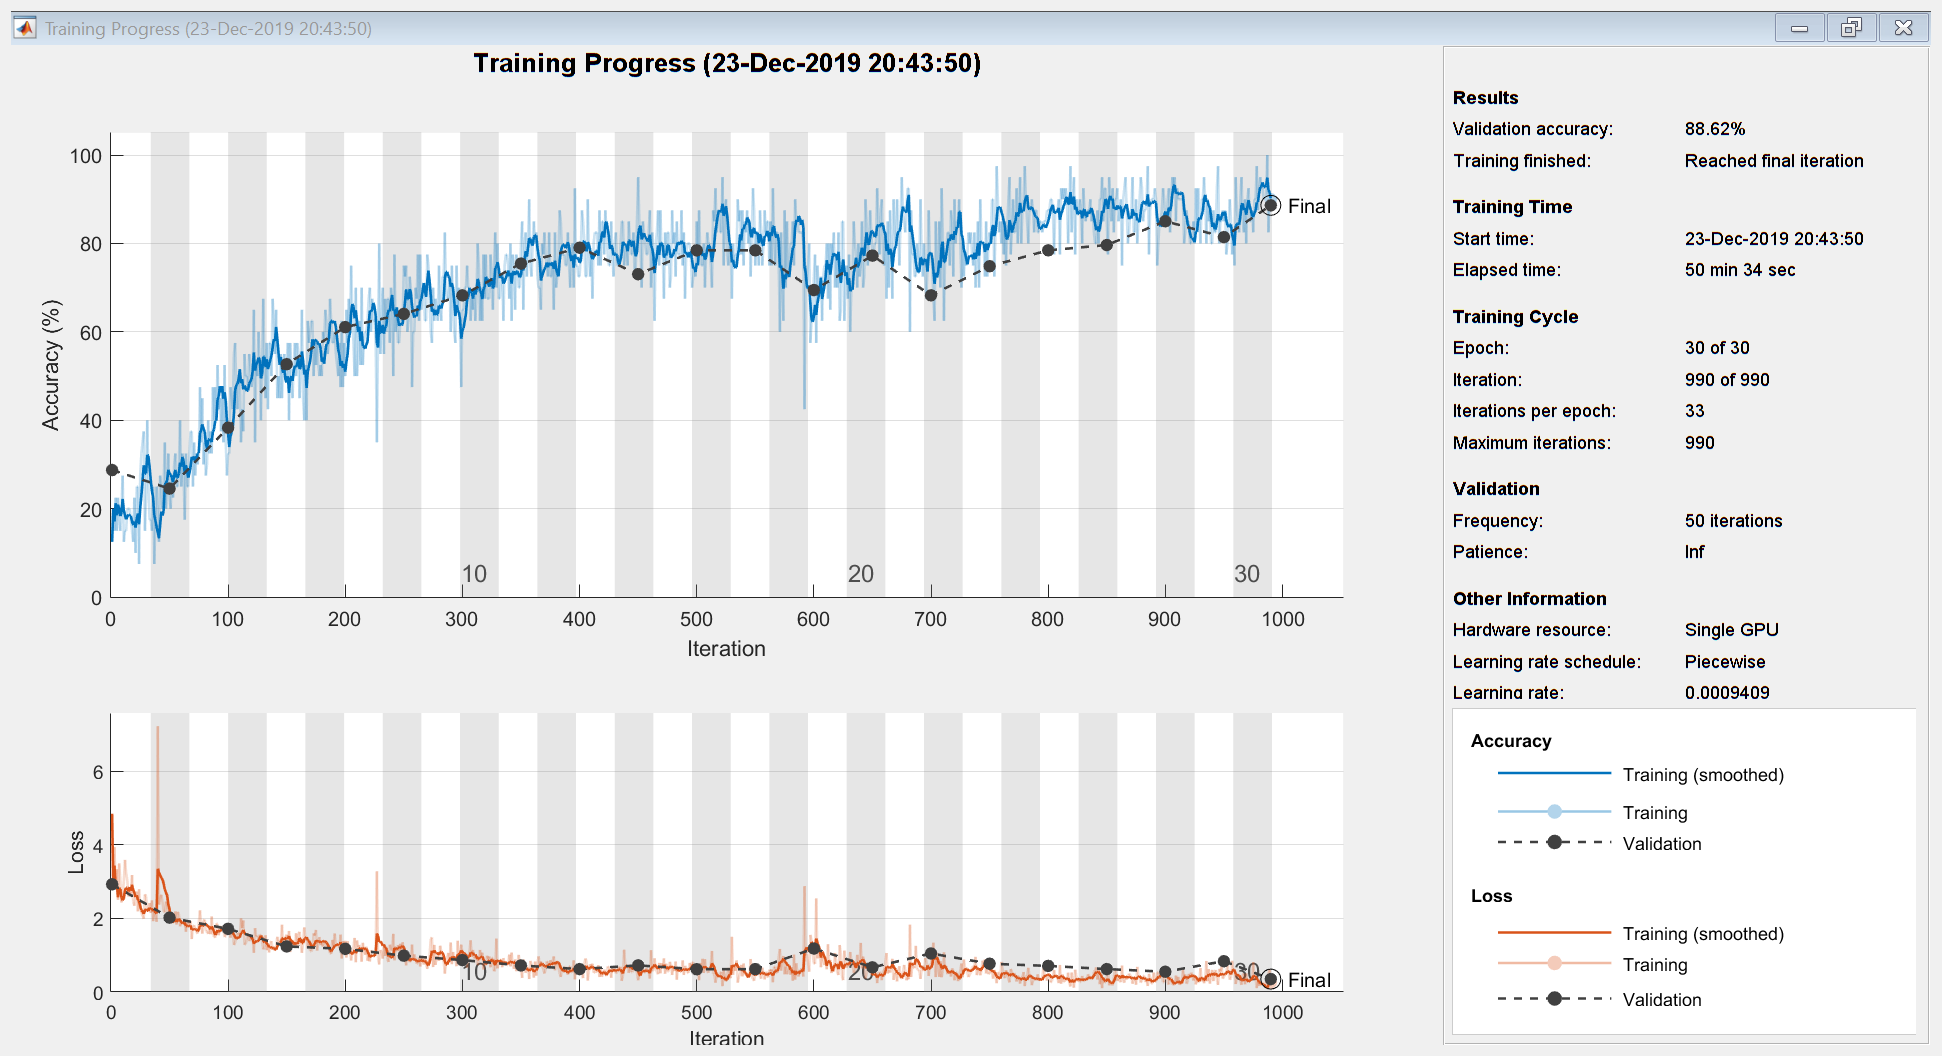

Training on single GPU.


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       12.50% |       28.74% |       4.8484 |       2.9296 |          0.0010 |
|       2 |          50 |       00:02:44 |       22.50% |       24.55% |       2.0988 |       2.0230 |          0.0010 |
|       4 |         100 |       00:05:26 |       32.50% |       38.32% |       1.8645 |       1.7176 |          0.0010 |
|       5 |         150 |       00:08:05 |       50.00% |       52.69% |       1.5594 |       1.2397 |          0.

options = trainingOptions('adam','plots','training-progress','MiniBatchSize',40, 'InitialLearnRate',0.001,'ValidationData',validimgs,"LearnRateSchedule","piecewise",'LearnRateDropFactor',0.97);
spectronet = trainNetwork(trainimgs,layers,options);